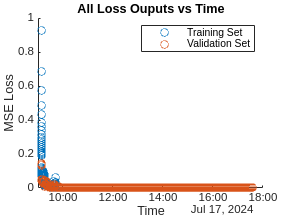

clear variables; close all; clc;

function match = parse_table(log, exp)
    full_exp = append('. ', exp,' 0.\d+');
    init_match = regexp(log.Var2, full_exp, 'match', 'once');
    match = array2table(init_match);
    match.time = log.Var1;
    match.Properties.VariableNames = ["val", "time"];
    match = rmmissing(match);
    real_data = erase(match.val, exp);
    match.val = str2double(real_data);
end


log = readtable("/home/achadbo/XPlaneAutolandScenario/models/2024-7-17/output.log");
val_match = parse_table(log, 'Mean Running Loss/val:');
train_match = parse_table(log, 'Mean Running Loss/train:');
epoch_val_match = parse_table(log, '#### Epoch Loss/val:');
epoch_train_match = parse_table(log, '#### Epoch Loss/train:');

scatter(train_match.time, train_match.val);
hold on;
scatter(val_match.time, val_match.val);
xlabel("Time");
ylabel("MSE Loss");
title("All Loss Ouputs vs Time");
legend({"Training Set", "Validation Set"}, 'Location', 'northeast');
hold off;

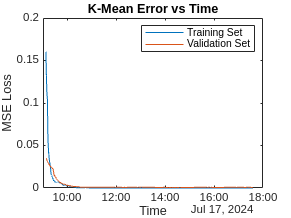



train_mean = movmean(train_match.val, 150);
val_mean = movmean(val_match.val, 150);
plot(train_match.time, train_mean)
hold on;
plot(val_match.time, val_mean);
xlabel("Time");
ylabel("MSE Loss");
title("K-Mean Error vs Time");
legend({"Training Set", "Validation Set"}, 'Location', 'northeast');
hold off;

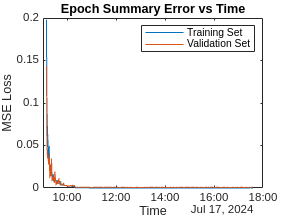


plot(epoch_train_match.time, epoch_train_match.val);
hold on;
plot(epoch_val_match.time, epoch_val_match.val);
xlabel("Time");
ylabel("MSE Loss");
title("Epoch Summary Error vs Time");
legend({"Training Set", "Validation Set"}, 'Location', 'northeast');
hold off;